## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Vectors**

## **Lab Session 1**

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Synthetic data**

**a) ***x = chirpTone(T, f1, f2, fs)**** definida no ficheiro chirpTone.m****.*

**b) **Listen the sound with f1 = 100, f2 = 2000 and fs = 4000 Hz.

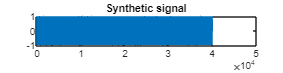

sData = chirpTone(10,100,2000,4000); %synthetic data
plot (sData);
title("Synthetic signal");

%soundsc(sData); %listen to it

**c) **Save the sound vector in an audio file to be read in normal audio players

fs = 4000; %sampling rate
audiowrite('synthetic.wav',sData,fs); %save in an audio file

# **2) Real data**

**a) Audio (1D)**

**i) **Read the audio file ”Let It Be.mp3”.

rData = audioread("Let It Be.mp3"); %real data

**b) **Compute the length of the file in seconds. Explain the approach you used. 

%informação acerca do ficheiro de áudio
audioinfo("Let It Be.mp3");
%retirar a sample rate
SRate = audioinfo("Let It Be.mp3").SampleRate;
%determinar o número de samples
SNumber = size(rData,1); % SNumber = audioinfo("Let It Be.mp3").TotalSamples
%a duração do ficheiro é igual ao número de samples sobre a sample rate
SLength = SNumber/SRate;

**c) **Reproduce the music backwards.

bData = flipud(rData); %flipped
%soundsc(bData);

**b) Electrocardiogram (1D)**

**i) **Read the *.mat file ”116m(2).mat”.

trace = load("116m(2).mat");

**ii) **Visualize the ECG trace and comment. **COMENTAR BIOMEDICAMENTE**

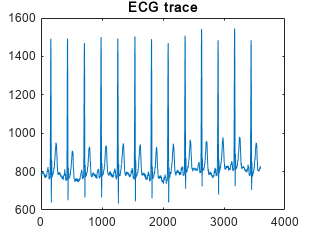

figure;plot(trace.val);
title("ECG trace");

**iii)** Estimate the sampling frequency that leads to a realistic ECG trace. 

%estimando que o sujeito está nos limites saudável de um adulto
fs=360;

**iv) **Detect the R peaks and estimate the heart rate (HR) from the inter-peak intervals. 

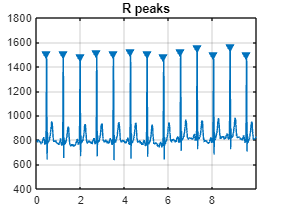

%extremos do sinal
findpeaks(trace.val,fs,'MinPeakHeight',1200); %visualize the peaks
title("R peaks");

[pks, locs] = findpeaks(trace.val,fs,'MinPeakHeight',1200) %indices

pks =         1492        1493        1469        1501        1493        1504        1490        1469        1508        1542        1484        1546        1485


locs =     0.4444    1.2056    1.9750    2.7333    3.4944    4.2750    5.0306    5.7889    6.5583    7.3083    8.0611    8.8139    9.5667


%heart rate estimation
time = diff(locs); %inter-peak intervals
hrAll = 60./time; %array with instantaneous hr
hr = mean(hrAll) %heart rate

hr = 78.9381

**b) Images (2D)**

**i) **Load the image "House8000.png" and creatively find hidden information in it.

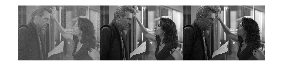

%read image
%img = imread("House8000.png");
%representar os canais RGB isoladamente
montage([img(:,:,1),img(:,:,2),img(:,:,3)],'size',[1 NaN]);

%canal R aparenta ter ruído ou distorção
Rvector = reshape(img(:,:,1),[],1); %vetorizar canal R
%soundsc(Rvector) %ouvir o sinal do vetor R

**ii) ** Suggest and implement a method to improve the quality of that information.

%finding noise, we can later achieve a "cleaner" red channel
Restim = (img(:,:,2)+img(:,:,3))/2 %estimativa do canal vermelho, (G+B)/2

Restim = 681×1024 uint8 matrix
   57   57   58   59   59   59   57   57   57   54   51   49   46   44   41   38   37   37   39   40   41   42   42   44   45   45   45   46   46   47   47   47   48   49   50   52   54   56   57   58   58   59   59   59   57   58   59   60   66   66
   57   57   58   59   59   59   57   57   57   54   51   49   46   44   41   38   37   38   39   40   41   41   42   43   44   44   45   45   46   46   47   47   48   48   50   52   54   55   57   57   58   59   59   59   58   59   60   62   67   66
   58   57   58   59   59   59   57   57   57   54   51   49   46   44   41   38   39   39   40   41   41   41   41   43   44   44   44   45   45   46   46   46   48   48   50   51   53   55   57   57   59   60   60   60   60   61   62   64   67   67
   58   57   58   58   58   58   57   57   57   55   52   49   47   44   41   39   40   40   41   41   41   41   41   42   43   43   44   44   45   45   46   46   48   48   50   52   54   55   57   57   59   61   61 

noise = img(:,:,1) - Restim %noise, definido como canal vermelho menos a sua estimativa

noise = 681×1024 uint8 matrix
   35   35   32    0   39   19   34   42   22   35   35   20   20   38   51   37   49   38   10   40   49   42   47   47   47   47   40   42   40   32   49   45   37   35   35   35   37   45   39   35   31   32   33   35   34   29   38   38   18   17
   35   35   33    0   37   32   34   44   17   33   38   22   24   39   49   41   48   36   25   42   51   43   42   44   47   46   34   39   44   31   39   49   41   36   26   35   37   41   37   33   32   34   31   31   33   33   36   40   18   19
   34   36   36    2   35   51   36   44   19   34   33   25   29   41   48   46   43   37   49   41   55   44   35   42   47   47   39   38   47   40   17   44   44   37   23   34   39   37   44   36   34   32   32   31   32   33   38   40   20   22
   34   35   46   14   33   52   36   39   22   32   34   29   35   43   53   45   41   43   63   39   51   44   37   36   44   43   40   37   45   42   17   39   43   38   19   33   37   34   47   33   33   29   32  

imwrite(noise,"HouseNoise.png") %save noise image
%soundsc(reshape(noise,[],1),8000); %listen to noise as a vector

**iii) **Suggest and implement a method to recover the original image. Compute the Signal-to-noise ratio of the recovered image comparing it with the original one. **SNR**

clean = img(:,:,:) - noise %recovered/clean image

clean = 681×1024×3 uint8 array
clean(:,:,1) =

    57    57    58    59    59    59    57    57    57    54    51    49    46    44    41    38    37    37    39    40    41    42    42    44    45    45    45    46    46    47    47    47    48    49    50    52    54    56    57    58    58    59    59    59    57    58    59    60    66    66    66    66    67    68    69    70    65    65    64    62    60    57    56    54    50    51    53    54    55    56    57    57    55    55    56    56    57    59    60    61    61    60    58    57    56    57    58    58    57    56    55    55    56    57    56    56    53    53    54    55    55    59    70    83    90   100   110   115   117   119   118   116   118   119   119   120   119   119   122   123   122   122   122   123   123   124   124   124   121   121   122   123   123   122   121   121   121   121   121   122   122   122   122   123   123   123   123   123   123   123   123   123   123   123   123   123   124   124   12

imwrite(clean,"HouseClean.png") %save clean image
original = imread("houseCuddy.jpg"); %read original image
snr = snr(original(:,:,1), img(:,:,1)-original(:,:,1)) %compute the SNR

Error using snr
Expected input number 1, X, to be one of these types:

double, single

Instead its type was uint8.

Error in snr>sampleSNR (line 180)
validateattributes(x,{'double','single'},{'finite'}, ...

Error in snr (line 119)
    [r, noisePow] = sampleSNR(input1, input2);


%estávamos à espera que o sinal subisse mas não
%ocorre alias, f de amostragem de 4000 não é alta o suficiente para que
%isto aconteça